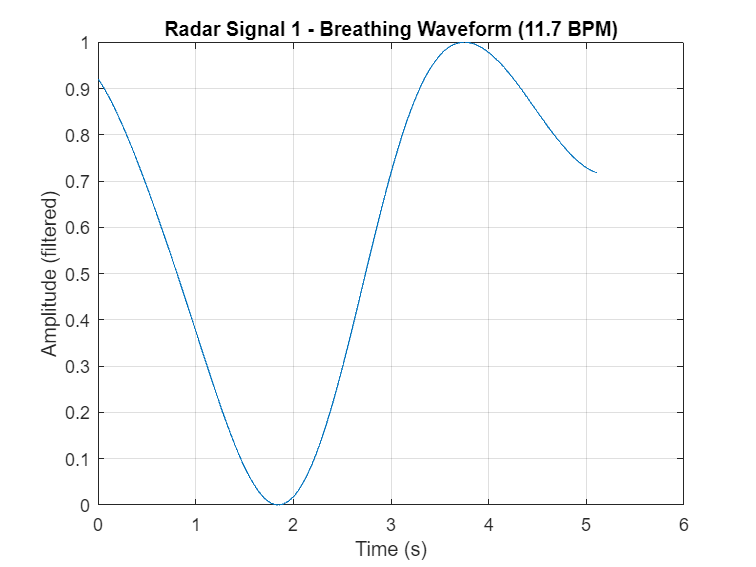

%%% Download dataset %%%
datasetZipFile = matlab.internal.examples.downloadSupportFile('SPT','data/SynchronizedRadarECGData.zip');
datasetFolder = fullfile(fileparts(datasetZipFile),'SynchronizedRadarECGData');
if ~exist(datasetFolder,'dir')     
    unzip(datasetZipFile,datasetFolder);
end

% Load all radar data
radarAllDs = signalDatastore([
    fullfile(datasetFolder,"trainVal","radar");
    fullfile(datasetFolder,"test","radar")
]);

% Read all radar signals
radarData = readall(radarAllDs);

%%% Settings %%%
fs = 200;
minBR = 6;
maxBR = 30;
minFreq = minBR/60;
maxFreq = maxBR/60;

% Bandpass filter for breathing rate
d = designfilt('bandpassiir', 'FilterOrder', 6, ...
    'HalfPowerFrequency1', minFreq, 'HalfPowerFrequency2', maxFreq, ...
    'SampleRate', fs);

%%%% Plot filtered breathing rate %%%%
tiledlayout(numSignalsToAnalyze, 1, 'Padding', 'none', 'TileSpacing', 'compact');

i = 1;
signal = radarData{i};
L = length(signal);
t = (0:L-1)/fs;

% Filter signal to isolate breathing component
filteredSignal = filtfilt(d, signal);
filteredSignal = (filteredSignal - min(filteredSignal)) / (max(filteredSignal) - min(filteredSignal));

% Estimate breathing rate using FFT
Y = fft(filteredSignal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = fs * (0:(L/2))/L;

idxBand = find(f >= minFreq & f <= maxFreq);
[~, maxIdx] = max(P1(idxBand));
domFreq = f(idxBand(maxIdx));
bpm = domFreq * 60;

% Plot filtered signal
plot(t, filteredSignal)
title(sprintf("Radar Signal %d - Breathing Waveform (%.1f BPM)", i, bpm))
xlabel("Time (s)")
ylabel("Amplitude (filtered)")
grid on